# ECPE 226 - Homework 04 - Regularization and Validation

    In this assignment, we used regularization and validation to provide better out of sample error due to overfitting. I used a ten fold cross validation to determine the best lambda (regularization parameter) to use on the USPS handwritten digit data, also instead of just using two features, the input data was nonlinearly transform to a 3rd order polynomial set. Finally, the final weighted vector was plotted.

% Clean up workspace
clear; close all; clc

## PART 1 - MATLAB CODE

% load data
load('usps_modified.mat');

% extract features (Intensity and Symmetry - x1 & x2; and labels - y)
[x, y] = get_features(data);

% change y labels to 1->1 everything else->-1
for i=1:5000
    if y(i) ~= 1
        y(i) = -1;
    end
end

% non-linear transform of the symmetry and intensity features to a 3rd order polynomial set
Z = non_lin_trans_3rd_order(x);

% lambda array
lambdas = [0.001, 0.01 0.1 0.25 0.5 0.75 1];

% ten-fold cross validation
[avg_w, avg_error] = ten_fold_cross_validation(Z, y, lambdas);


## PART 2 - PLOTS

    After completing the ten fold cross validation, the average error for each lambda was calculated and plotted on a bar graph as shown below. From this, we can note two very important details. The first is that the out-of-sample error was generally higher than the in-sample error but not by much, which is expected and good. Finally, the best out-of-sample error corresponded to the 0.75 lambda in this case. Which means for the next plots, this is the lambda that will be used as it is our best result.

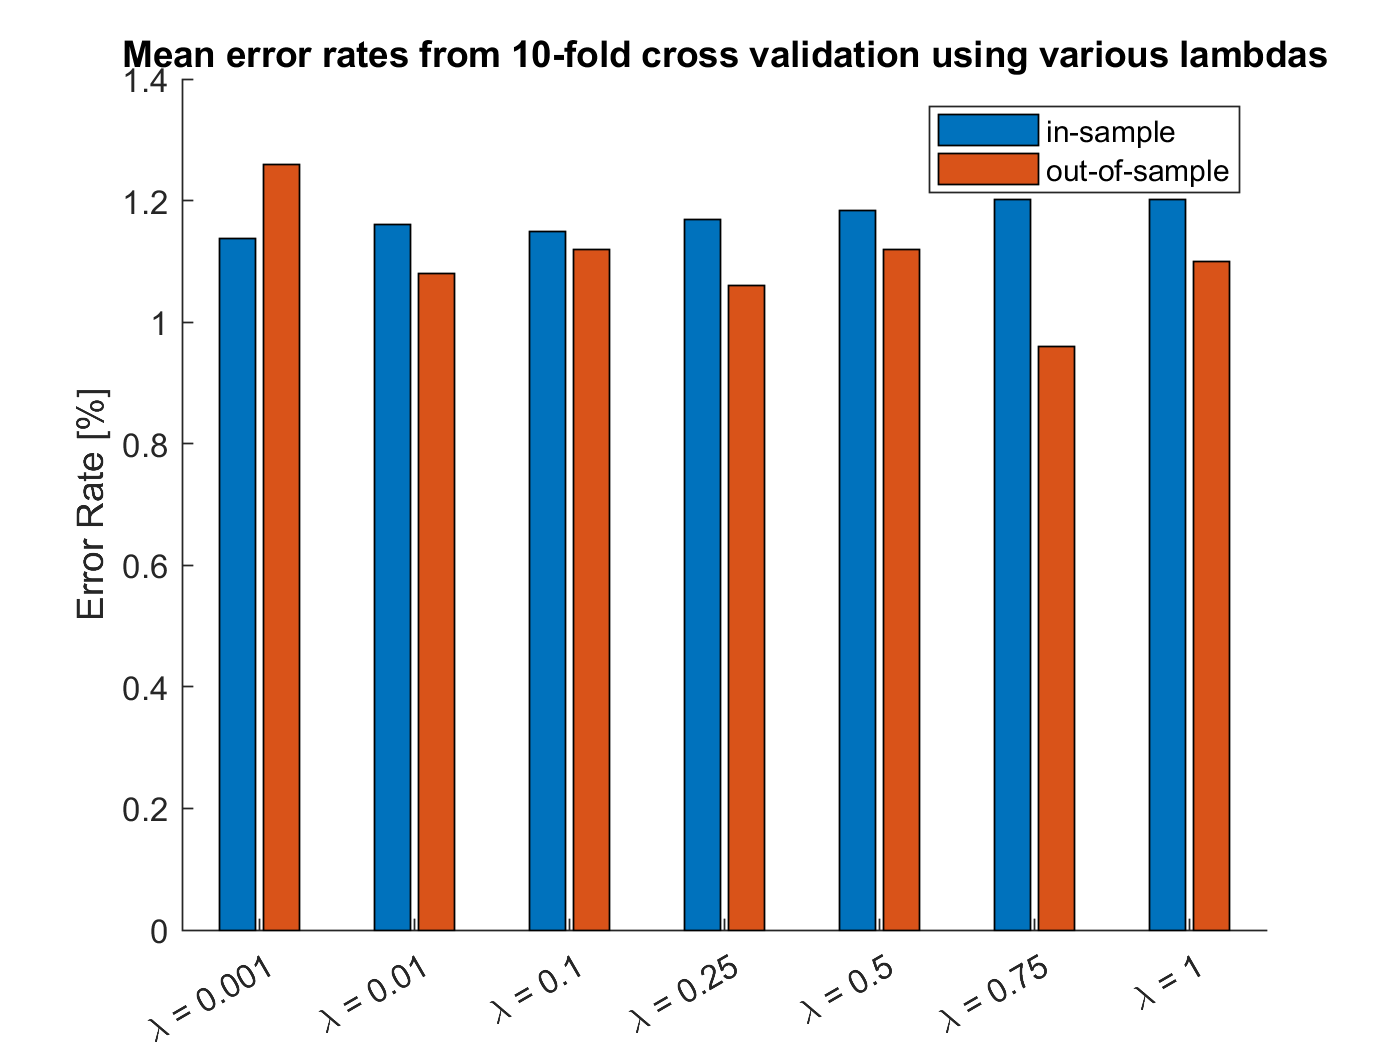

% initialize bar graph arrays
cat = [strcat("\lambda = ", num2str(lambdas(1)))];
bar_err = [avg_error(1, 1) avg_error(2, 1)];

% loop through lambdas
for i=2:length(lambdas)
    cat = [cat, strcat("\lambda = ",num2str(lambdas(i)))];
    bar_err = [bar_err; avg_error(1, i) avg_error(2, i)];
end
figure
hold on

% Plot bar graph of error rates for N=400
c = categorical(cat);
bar(c, bar_err)
title("Mean error rates from 10-fold cross validation using various lambdas")
legend('in-sample', 'out-of-sample')
ylabel("Error Rate [%]")

    After that, the weighted vectors for each lambda was tabularized and from this we can see that generally, as the lambda increases the weighted term decreases in magnitude. So as the lambda increases the weighted terms become less "wild" and more stable.

% Tabulate average weight vector for each lambda
T = table(lambdas', avg_w(1, :)', avg_w(2, :)', avg_w(3, :)', avg_w(4, :)', avg_w(5, :)', ...
    avg_w(6, :)', avg_w(7, :)', avg_w(8, :)', avg_w(9, :)', avg_w(10, :)');

T.Properties.VariableNames = {'Lambda', 'w1', 'w2', 'w3', 'w4', 'w5', 'w6', 'w7', 'w8', 'w9', 'w10'}

T = 7×11 table
    Lambda       w1          w2           w3         w4          w5          w6          w7          w8         w9        w10  
    ______    ________    _________    ________    _______    ________    _________    _______    ________    _______    ______

    0.001      -0.8831       1.5221    -0.63686     4.5114     -1.8537     -0.64877     4.0474     -1.5044     -3.303    1.2302
     0.01     -0.88055       1.5437     -0.6345     4.5969       -1.83     -0.66268     4.1438     -1.4385    -3.3129    1.2185
      0.1     -0.96347      0.82383    -0.56616     2.7852     -1.3585     -0.40289     2.7546    

    Finally, the best hypothesis curve was plotted using the corresponding best lambda. The points that were correctly classified were plotted as blue or green, while the incorrectly classified were plotted as red or magneta. The ones were 'x' and the other digits were 'o'.

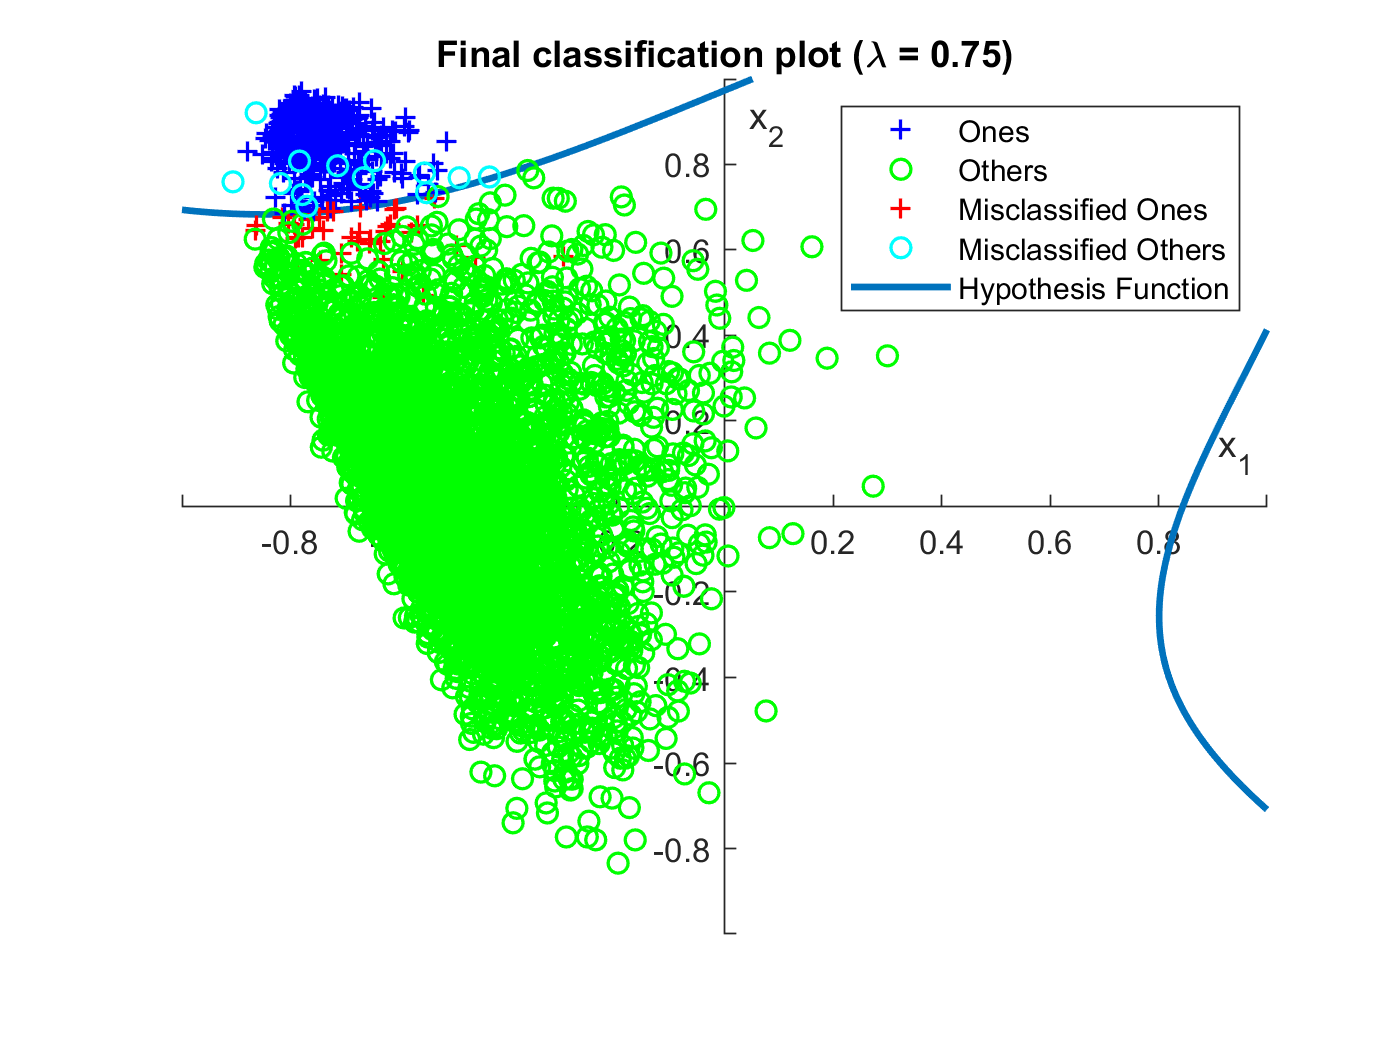

% plot the training dataset
figure
hold on

% plot hypothesis line
p5 = plothypothesis3(avg_w(:, 6));

% plot data points
for i = 1:length(y)
    if (sign(dot(avg_w(:,6), [1 Z(i, :)])) == y(i))
        if y(i) == 1
            p1 = scatter(x(i,1),x(i,2),'blue','+','LineWidth',1); % correctly classified 1
        else
            p2 = scatter(x(i,1),x(i,2),'green','o','LineWidth',1); % correctly classified other
        end
    else
        if y(i) == 1
            p3 = scatter(x(i,1),x(i,2),'red','+','LineWidth',1); % incorrectly classified 1
        else
            p4 = scatter(x(i,1),x(i,2),'cyan','o','LineWidth',1); % incorrectly classified other
        end
    end
end
axis([-1 1 -1 1])
xlabel('x_1'); ylabel('x_2');
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';

% add title
title("Final classification plot (\lambda = 0.75)");

% add legend
legend([p1, p2, p3, p4, p5], {'Ones', 'Others', 'Misclassified Ones', 'Misclassified Others', 'Hypothesis Function'})